## Removing miss-segmented data - analysing r2 data

The computer vision algorithm detect cells present in a timepoint from microscopy, returning the location and area of all cells in a timepoint. Division events are detected from these outputs of the computer vision algorithm. Both of these steps are prone to errors. Prior to analysing cell lifetimes, those arrising from errors in these two steps must first be eliminated.

Each cell lifetime is composed of multiple datapoints obtained by aquisitions from a capture from the epi-flourescent microscope. A linear fit is applied to these points to predict the growth rates. The first step taken to eliminate erroneous lifetimes is to remove lifetimes with a low r2 value between the timepoints and the fit growth rate.

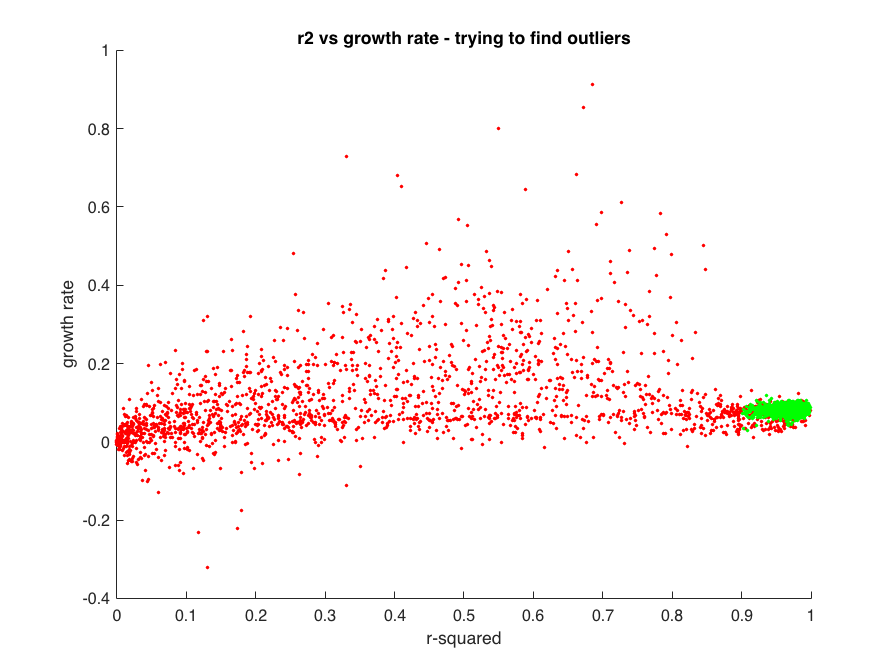

figure
hold on
scatter(v_results.v_r2(~v_results.v_keep),v_results.v_growth_rate(~v_results.v_keep),5,'filled','r')
scatter(v_results.v_r2(v_results.v_keep),v_results.v_growth_rate(v_results.v_keep),5,'filled','g')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")
hold off

Most outliers can be removed by limiting r2 to not include perfect fits, most likely due to a limited number of overvations. Since we are excluding the first and last point observed for a lifetime, up to 4 observations will lead to a perfect fit (2 points needed for linear fit). 

These points are most likely miss segmentations. The sampling rate for this experiment is 2 minutes - so 4 observed points for a cell-lifetime will relate to at most a 12 minute division time - which has never been observed in E Coli, even for strains optimized to have a fast division time(cite). In comparision here we are expressing either flouresent or also β-lactamase - our prior assumption is cell dvision times will not be lower than the fastest divison times of the WT strain in ideal conditions.

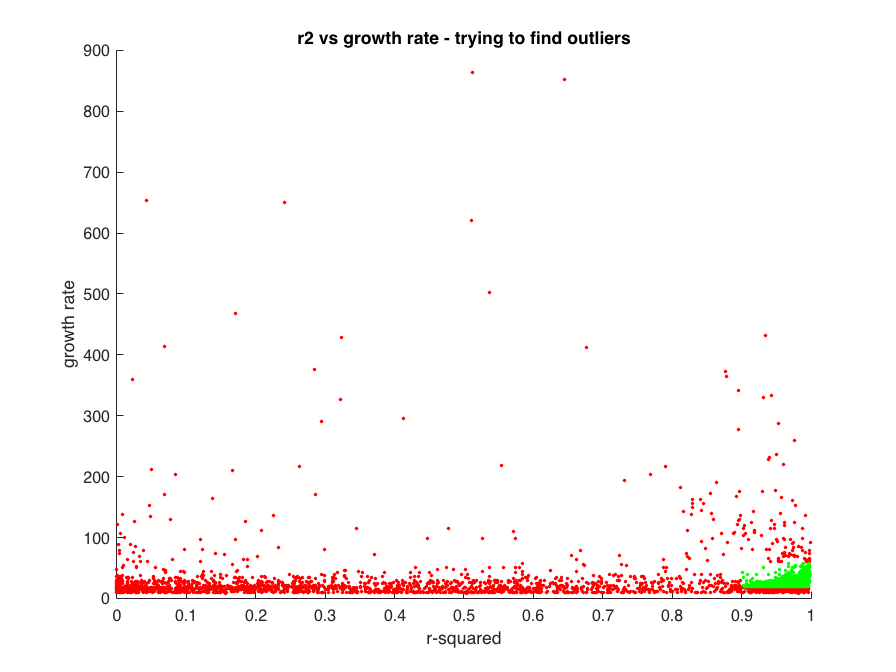

figure
hold on
scatter(v_results.v_r2(~v_results.v_keep),v_results.v_division_time(~v_results.v_keep),5,'filled','r')
scatter(v_results.v_r2(v_results.v_keep),v_results.v_division_time(v_results.v_keep),5,'filled','g')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")
hold off

The number of points retained when removing r2 values above max_r2 and less than min_r2 are:

percent_keeping = sum(v_results.v_keep)/length(v_results.v_keep)

percent_keeping = 0.6553

## 1. Number of cells in each population

### Finding threshold to seperate populations

Looking at the retained values, we can segment the population in two - those expressing YFP and those that are not.

The cells expressing YFP must contain the plasmid ampR:YFP

The cells not expressing YFP either didn't contain the plasmid initially or lost them

By obeserving the histogram of YFP intentsity we can segment these two populations, a value of 250 seems to be a good threshold.

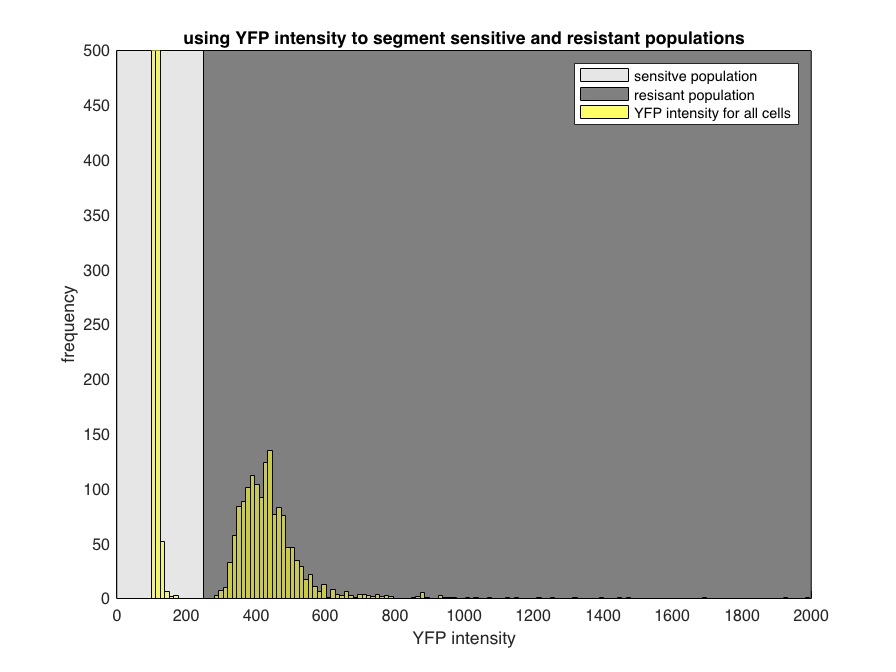

clf
threshold = 250;
hold on
patch([threshold,0,0,threshold],[0,0,500,500],0.9*ones(1,3))
patch([2000,threshold,threshold,2000],[0,0,500,500],0.5*ones(1,3))
histogram(v_results.v_yfp(v_results.v_keep),1000,'FaceColor','yellow')
ylim([0 500])
xlim([0 2000])
xlabel("YFP intensity")
ylabel("frequency")
legend("sensitve population","resisant population","YFP intensity for all cells")
title("using YFP intensity to segment sensitive and resistant populations")
sensitive_id = v_results.v_keep & (v_results.v_yfp<250);
resistant_id = v_results.v_keep & (v_results.v_yfp>=250);
number_sensitive_lifetimes = sum(sensitive_id);
number_resistant_lifetimes = sum(resistant_id);
hold off

### 1a: population distribution of all observed lifetimes in experiemnts

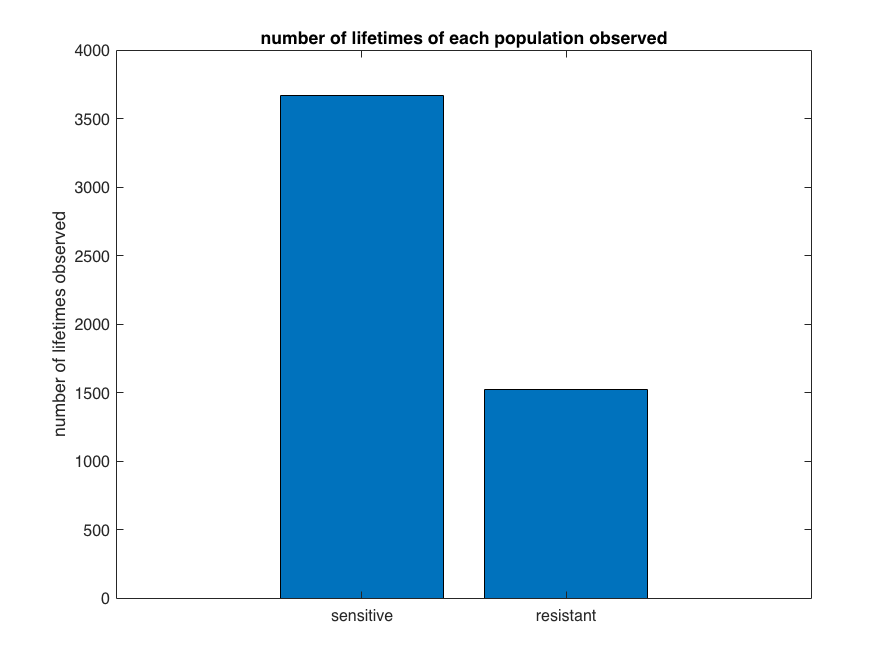

bar([number_sensitive_lifetimes,number_resistant_lifetimes]);
%xlabel(["sensitive","resistant"])
set(gca,'xticklabel',["sensitive","resistant"])
ylabel("number of lifetimes observed")
title("number of lifetimes of each population observed")

Note there seems to be a large discreptancy between number of lifetimes experience in each population

Start off by looking at the division of mother cells at start in each cell

#### 1b: population distribution of all mother cells over timepoints

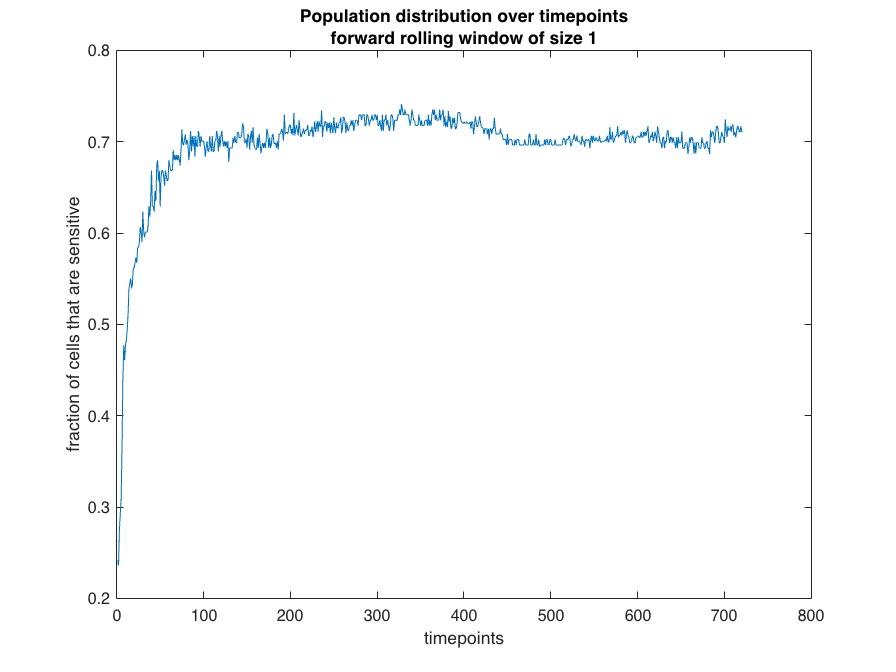

frac_sens = nan(1,size(data,2));
num_cells_at_t = nan(1,size(data,2));
length_window = 1;
for t=length_window:size(data,2)
    cells_at_t = nanmean(data(:,t-length_window+1:t,36),2);%data(:,t,36);
    cells_at_t=(cells_at_t(~isnan(cells_at_t)));
    sensit = cells_at_t<threshold;
    frac_sens(1,t) = sum(sensit)/length(cells_at_t);
end
clf
plot(frac_sens)
xlabel('timepoints')
ylabel('fraction of cells that are sensitive')
title(["Population distribution over timepoints","forward rolling window of size "+length_window])

#### 1c: population distribution of mother cell lifetimes wrt number of lifetimes into experiment

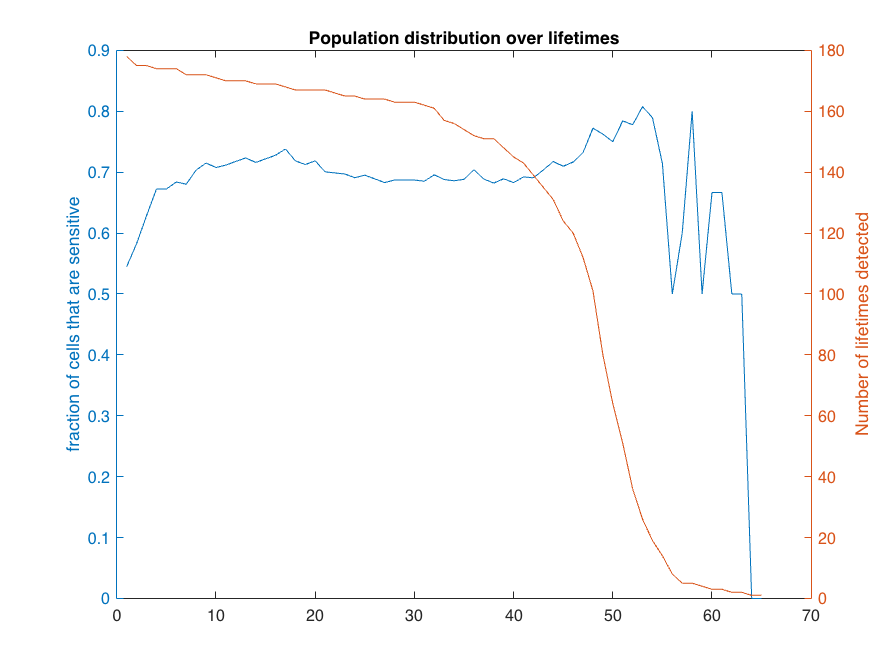

frac_sens = nan(1,size(results.yfp,2));
num_cells_at_t = nan(1,size(results.yfp,2));
for t=1:size(results.yfp,2)
    cells_at_t = nonzeros(results.yfp(:,t));
    sensit = cells_at_t<threshold;
    frac_sens(1,t) = sum(sensit)/length(cells_at_t);
    num_cells_at_t(1,t) = length(cells_at_t);
end
clf
title("Population distribution over lifetimes")
yyaxis left
plot(frac_sens)
ylabel('fraction of cells that are sensitive')
yyaxis right
plot(num_cells_at_t)
ylabel('Number of lifetimes detected')

### 1d: population distribution of ALL cells (any cell detected from fiji processing) over timepoints

should relate the the stationary phase abundance of these strains

all_data = [];
frac = [];

for i = 1:20
    for j = 1:9
        d = all_fiji_data{i,j};
        if(size(d,1)~=0)
            all_data = [all_data; d(:,[28,36])];
        end
    end
end

pop_dist = zeros(1,721);
total = zeros(1,721);
for t=1:721
    dist = all_data(all_data(:,1)==t,2)<threshold;
    pop_dist(1,t) = sum(dist)/length(dist);
    total(1,t) = length(dist);
end

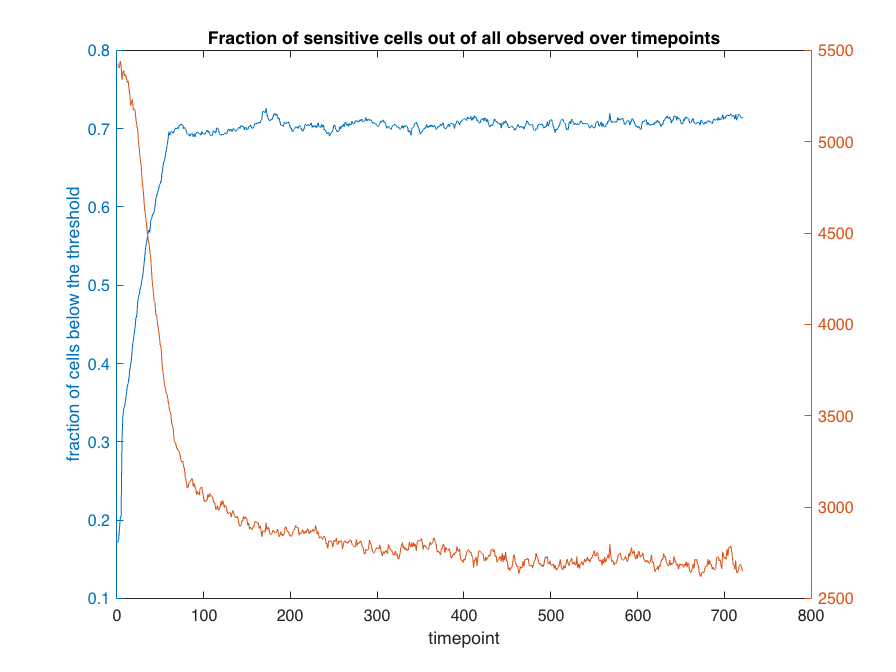

clf
title("Fraction of sensitive cells out of all observed over timepoints")
yyaxis left
plot(pop_dist)
xlabel("timepoint")
ylabel("fraction of cells below the threshold")
yyaxis right
plot(total)

## Lag time

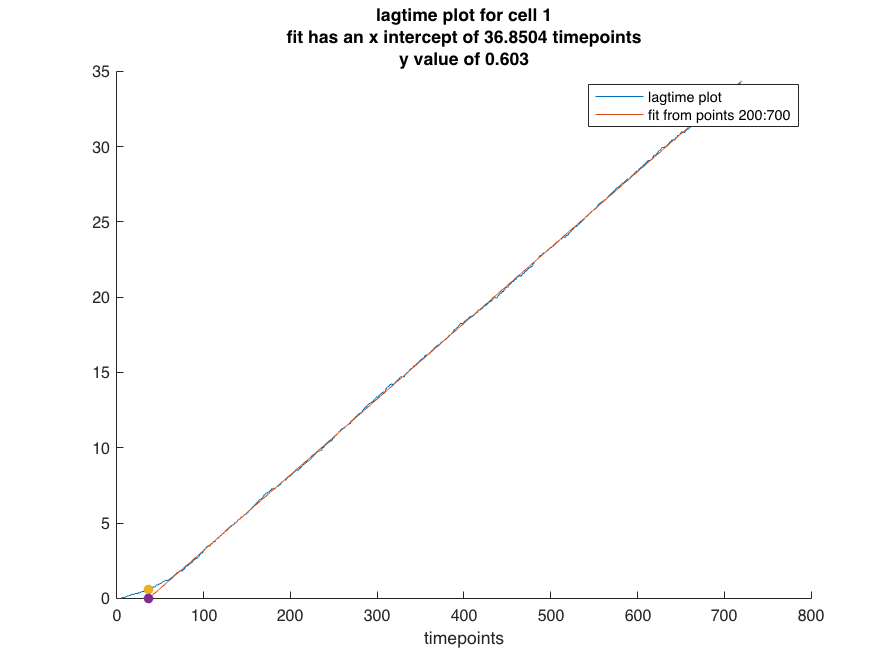

cell_num = 1;
range_fit = 200:700;
lagt = lagtime(0.06,log(data(cell_num,:,2)));
p = polyfit(range_fit,lagt(cell_num,range_fit),1);
fit = polyval(p,1:720);
clf
hold on
plot(lagt);
plot(1:720,fit);
x0 = interp1(fit,1:720,0);
title(["lagtime plot for cell "+cell_num,"fit has an x intercept of "+ x0 + " timepoints", "y value of "+lagt(round(x0))])
scatter(x0,lagt(round(x0)),'filled')
scatter(x0,0,'filled')

ylim([0,35])

legend("lagtime plot", "fit from points 200:700")
xlabel("timepoints")

hold off

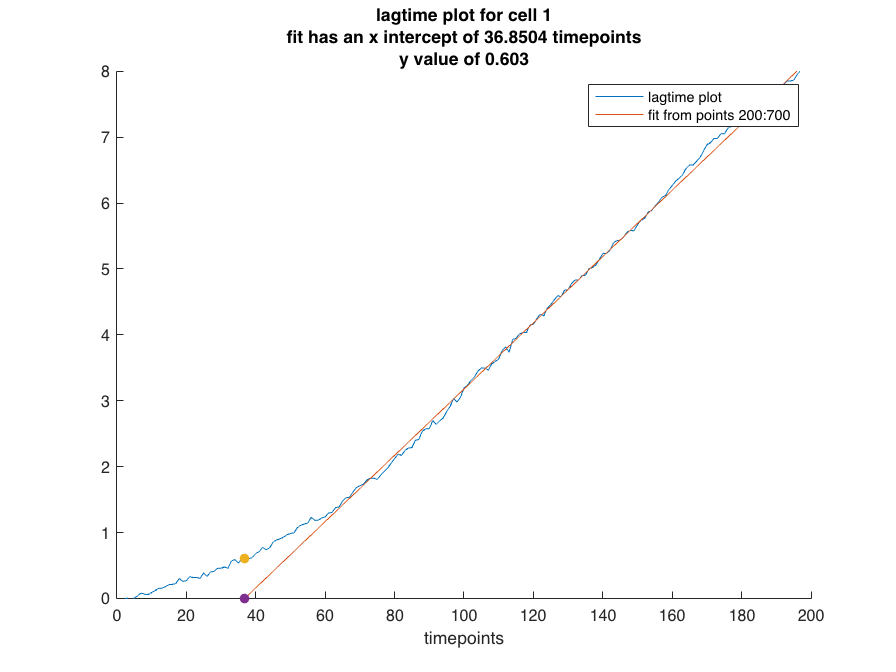

cell_num = 1;
range_fit = 200:700;
lagt = lagtime(0.06,log(data(cell_num,:,2)));
p = polyfit(range_fit,lagt(cell_num,range_fit),1);
fit = polyval(p,1:720);
clf
hold on
plot(lagt);
plot(1:720,fit);
x0 = interp1(fit,1:720,0);
title(["lagtime plot for cell "+cell_num,"fit has an x intercept of "+ x0 + " timepoints", "y value of "+lagt(round(x0))])
scatter(x0,lagt(round(x0)),'filled')
scatter(x0,0,'filled')
xlim([0 200])
ylim([0 8])

legend("lagtime plot", "fit from points 200:700")
xlabel("timepoints")

hold off

Lag time for all cells

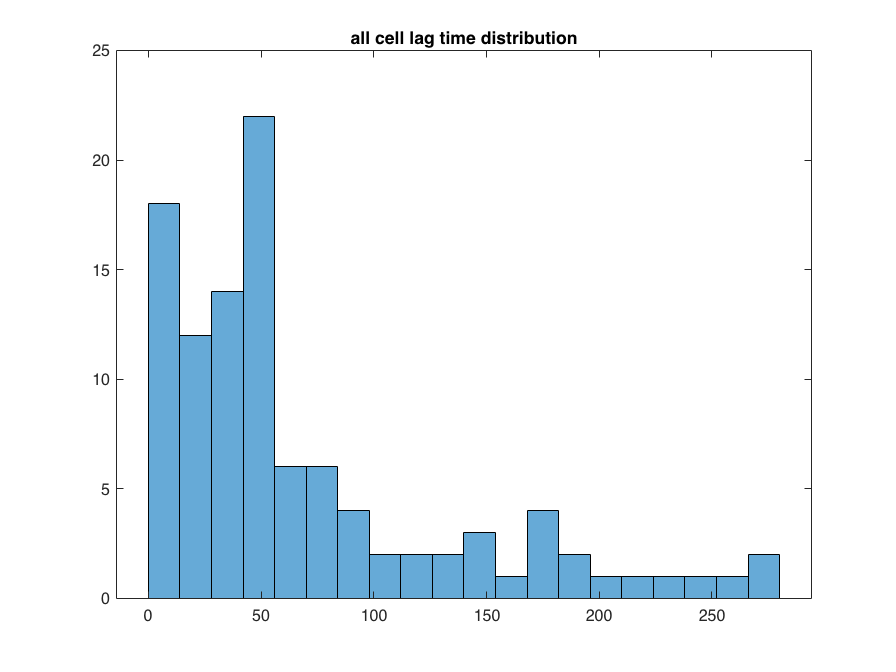

lag_time = nan(1,178);
for cell_num = 1:178
    range_fit = 200:700;
    lagt = lagtime(0.06,log(data(cell_num,:,2)));
    p = polyfit(range_fit,lagt(1,range_fit),1);
    if(~isnan(p(1,1)))
        fit = polyval(p,1:720);
        x0 = interp1(fit,1:720,0);
        lag_time(1,cell_num) = x0;
    end
end
clf
histogram(lag_time,20)
title("all cell lag time distribution")

Looking at the growth rate distributions

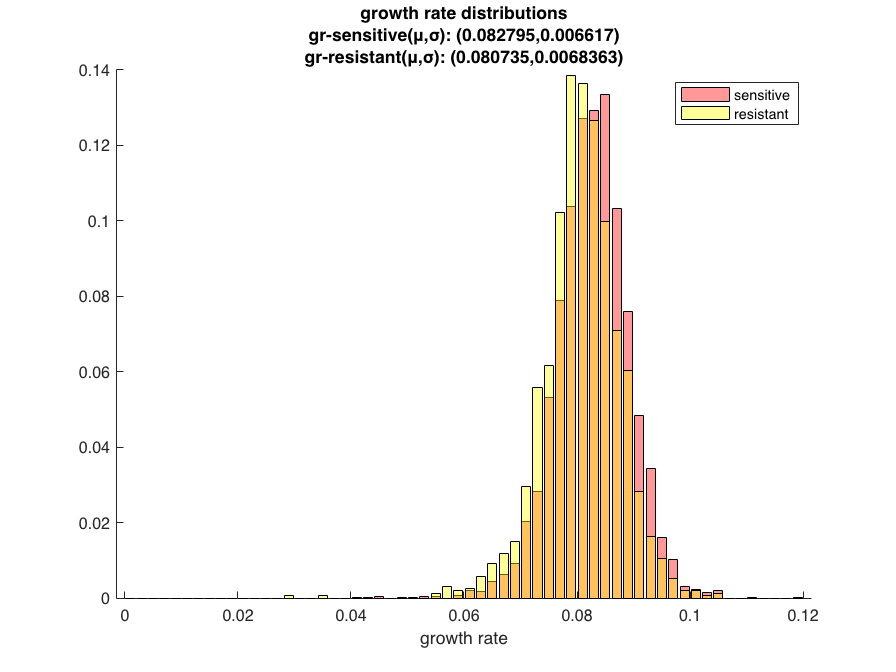

growth_rate_mean_sensitive = mean(v_results.v_growth_rate(sensitive_id));
growth_rate_stdd_sensitive = std(v_results.v_growth_rate(sensitive_id));
growth_rate_mean_resistant = mean(v_results.v_growth_rate(resistant_id));
growth_rate_stdd_resistant = std(v_results.v_growth_rate(resistant_id));
res = 0.002;
E = 0:res:0.12;

[sN,sedges] = histcounts(v_results.v_growth_rate(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(v_results.v_growth_rate(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off
xlabel("growth rate")
title(["growth rate distributions",...
    "gr-sensitive(μ,σ): ("+num2str(growth_rate_mean_sensitive)+","+...
    num2str(growth_rate_stdd_sensitive)+")", ...
    "gr-resistant(μ,σ): ("+num2str(growth_rate_mean_resistant)+","+...
    num2str(growth_rate_stdd_resistant)+")"])
legend(["sensitive","resistant"])

Repeating for the division time distribution

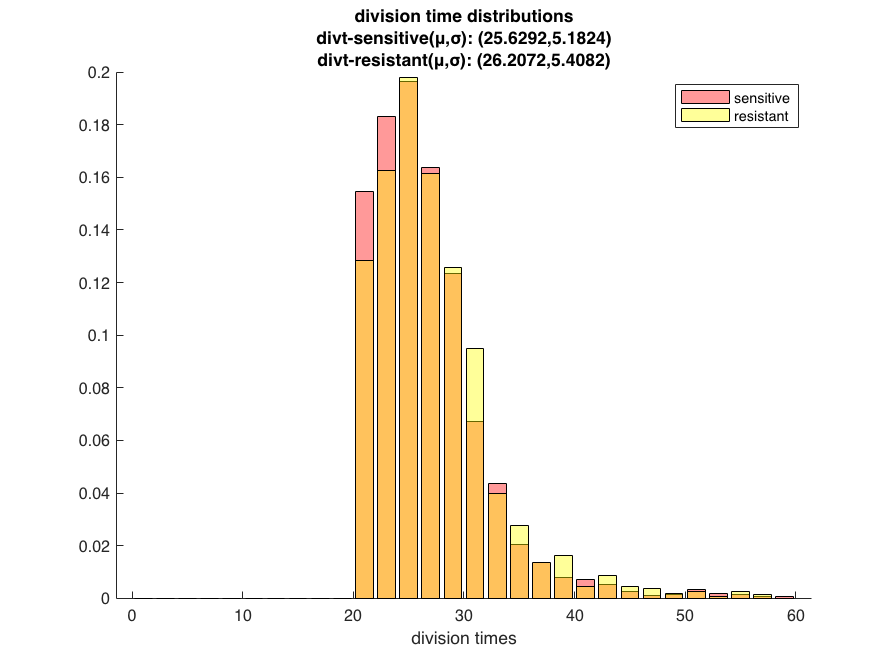

division_time_mean_sensitive = mean(v_results.v_division_time(sensitive_id));
division_time_stdd_sensitive = std(v_results.v_division_time(sensitive_id));
division_time_mean_resistant = mean(v_results.v_division_time(resistant_id));
division_time_stdd_resistant = std(v_results.v_division_time(resistant_id));
res = 2;
E = 0:res:60;
[sN,sedges] = histcounts(v_results.v_division_time(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(v_results.v_division_time(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off
xlabel("division times")
title(["division time distributions",...
    "divt-sensitive(μ,σ): ("+num2str(division_time_mean_sensitive)+","+...
    num2str(division_time_stdd_sensitive)+")", ...
    "divt-resistant(μ,σ): ("+num2str(division_time_mean_resistant)+","+...
    num2str(division_time_stdd_resistant)+")"])
legend(["sensitive","resistant"])